**Step 0**: Preprocesseing

clearvars
clc
%run_preprocessing

Start logging

if ~isfolder('out/implicitmf')
    mkdir('out/implicitmf');
end

logFile = fullfile('out', 'implicitmf', 'log.txt');
fid = fopen(logFile, 'a');  % 'a' = append to file


**Step 1**: Load Preprocessed Data (if already done before)

load('out/train.mat');   % R_train, train_u, train_i, train_ctx
load('out/val.mat');     % val_u, val_i, val_ctx
load('out/test.mat');    % test_u, test_i, test_ctx

**Step 2**: Train Implicit MF through different variables

addpath('Implicit');
addpath('data'); 
MAXOBJ = 30;

fprintf('[%s]Run Started\n',string(datetime('now')))

[06-Sep-2025 19:47:24]Run Started


[06-Sep-2025 19:47:24][1/30] Training dims=117, lambda=0.0313, alpha=49, iter=10 
 [06-Sep-2025 19:48:49] Iter 1/10 done. time: 82.12s
[06-Sep-2025 19:50:12] Iter 2/10 done. time: 82.52s
[06-Sep-2025 19:51:36] Iter 3/10 done. time: 83.87s
[06-Sep-2025 19:52:59] Iter 4/10 done. time: 83.12s
[06-Sep-2025 19:54:23] Iter 5/10 done. time: 83.73s
[06-Sep-2025 19:55:46] Iter 6/10 done. time: 83.06s
[06-Sep-2025 19:57:09] Iter 7/10 done. time: 83.62s
[06-Sep-2025 19:58:32] Iter 8/10 done. time: 82.80s
[06-Sep-2025 19:59:56] Iter 9/10 done. time: 83.91s
[06-Sep-2025 20:01:21] Iter 10/10 done. time: 84.55s
[06-Sep-2025 20:07:17][1/30]Evaluation dims=117, lambda=0.0313, alpha=49, iter=10 → Recall@20=0.9088, NDCG@20=0.7301
|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |         dims |       lambda |        alpha |
|      | result |             | runtime  

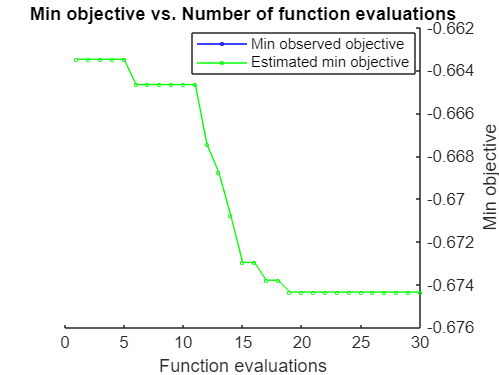

fprintf(fid,'[%s]Run Started\n',string(datetime('now')));
vars = [
    optimizableVariable('dims', [10, 200], 'Type', 'integer')
    optimizableVariable('lambda', [0.001, 0.5])
    optimizableVariable('alpha', [10, 50], 'Type', 'integer')
];

resultsBO = bayesopt(@(x) objectiveFunction(x, R_train, val_u, val_i,fid,MAXOBJ), ...
    vars, ...
    'MaxObjectiveEvaluations', MAXOBJ, ...
    'IsObjectiveDeterministic', true, ...
    'Verbose', 1);

**Step 3: **Evaluate the best model on the test set 

best_id = resultsBO.IndexOfMinimumTrace(30)

best_id = 19

results = resultsBO.XAtMinObjective; 
model_name = sprintf('model%d_dims%d_lambda%.2f_alpha%d_iter10.mat', ...
                     best_id, results.dims, results.lambda, results.alpha);
                 
load(fullfile('out/implicitmf', model_name), 'U', 'V');

% Evaluate on test set
[recall20_test, ndcg20_test] = evaluate(U, V, test_u, test_i, R_train);

fprintf('[%s] Test results → Recall@20=%.6f, NDCG@20=%.6f\n', ...
    string(datetime('now')), recall20_test, ndcg20_test);

[07-Sep-2025 11:21:34] Test results → Recall@20=0.9003, NDCG@20=0.6903


fprintf(fid,'[%s] Test results → Recall@20=%.6f, NDCG@20=%.6f\n', ...
    string(datetime('now')), recall20_test, ndcg20_test);

fclose(fid);
